Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment -2** 

% Defining some common functions to be used in this experiment
delta = @(n) n == 0;

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

mean = 0; variance = 1;
% generating a gaussian random sequence having 101 values
gaussian_random_sequence = mean + variance.*randn(1, 101);
% mapping the 101 values generated above, on the range (-50 <= n <= 50)
w = @(n) gaussian_random_sequence(n + 51);

**Q1:**

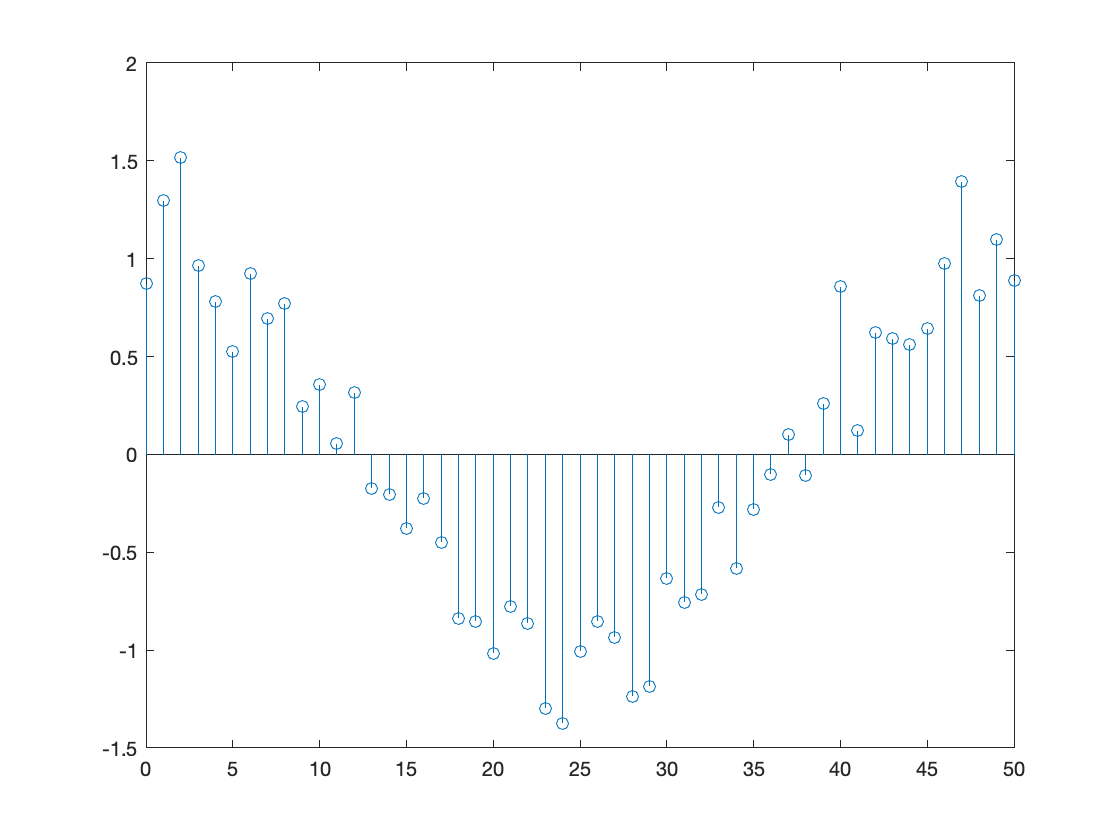

% (a)
x = @(n) cos(0.04 * pi * n) + (0.2 * w(n));
n = 0:50;
figure; stem(n, x(n));

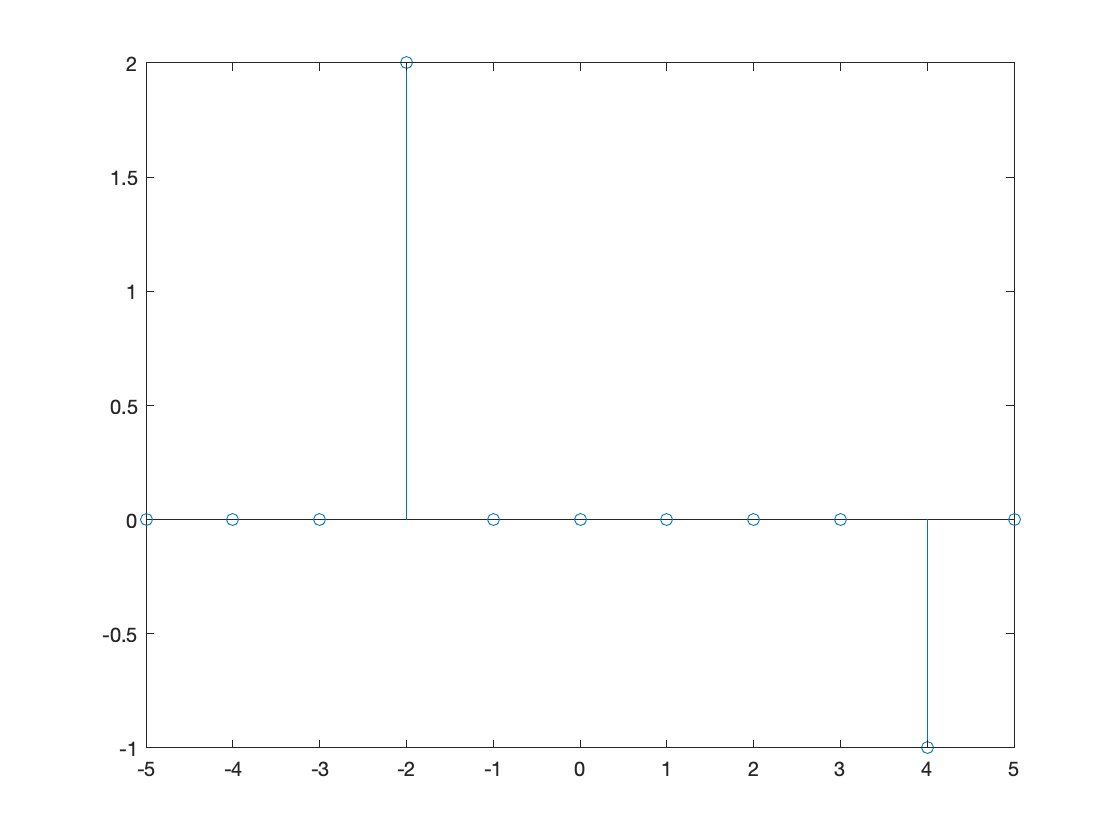


% (b)
x = @(n) (2 * delta(n + 2)) - delta(n - 4);
n = -5:5;
figure; stem(n, x(n));

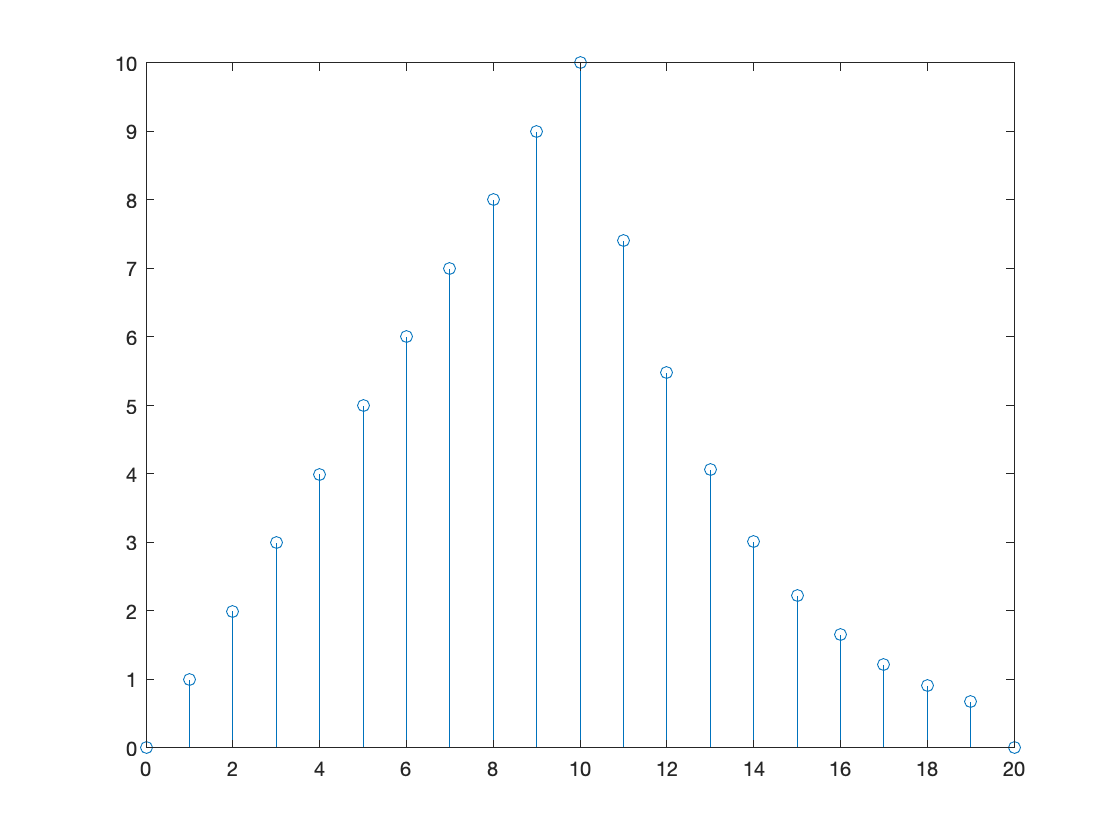


% (c)
x = @(n) (n .* (u(n) - u(n - 10)))...
    + (10 .* exp(-0.3 * (n - 10)) .* (u(n - 10) - u(n - 20)));
n = 0:20;
figure; stem(n, x(n));

**Q2:**

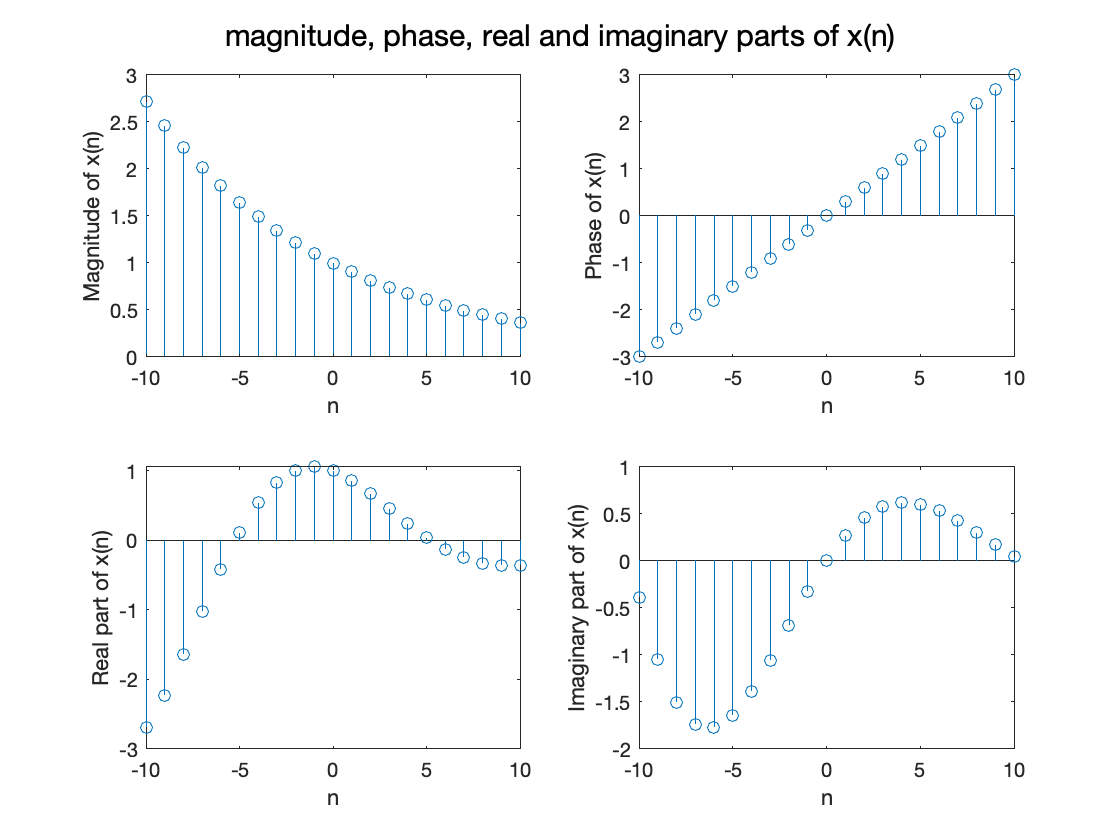

x = @(n) exp((-0.1 + 0.3i) .* n);
n = -10:10;

xn = x(n);
magnitude = abs(xn);
phase = angle(xn);
realPart = real(xn);
imaginaryPart = imag(xn);

figure;
subplot(2, 2, 1);
stem(n, magnitude);
xlabel("n"); ylabel("Magnitude of x(n)");

subplot(2, 2, 2);
stem(n, phase);
xlabel("n"); ylabel("Phase of x(n)");

subplot(2, 2, 3);
stem(n, realPart);
xlabel("n"); ylabel("Real part of x(n)");

subplot(2, 2, 4);
stem(n, imaginaryPart);
xlabel("n"); ylabel("Imaginary part of x(n)");

sgtitle("magnitude, phase, real and imaginary parts of x(n)");

**Q3:**

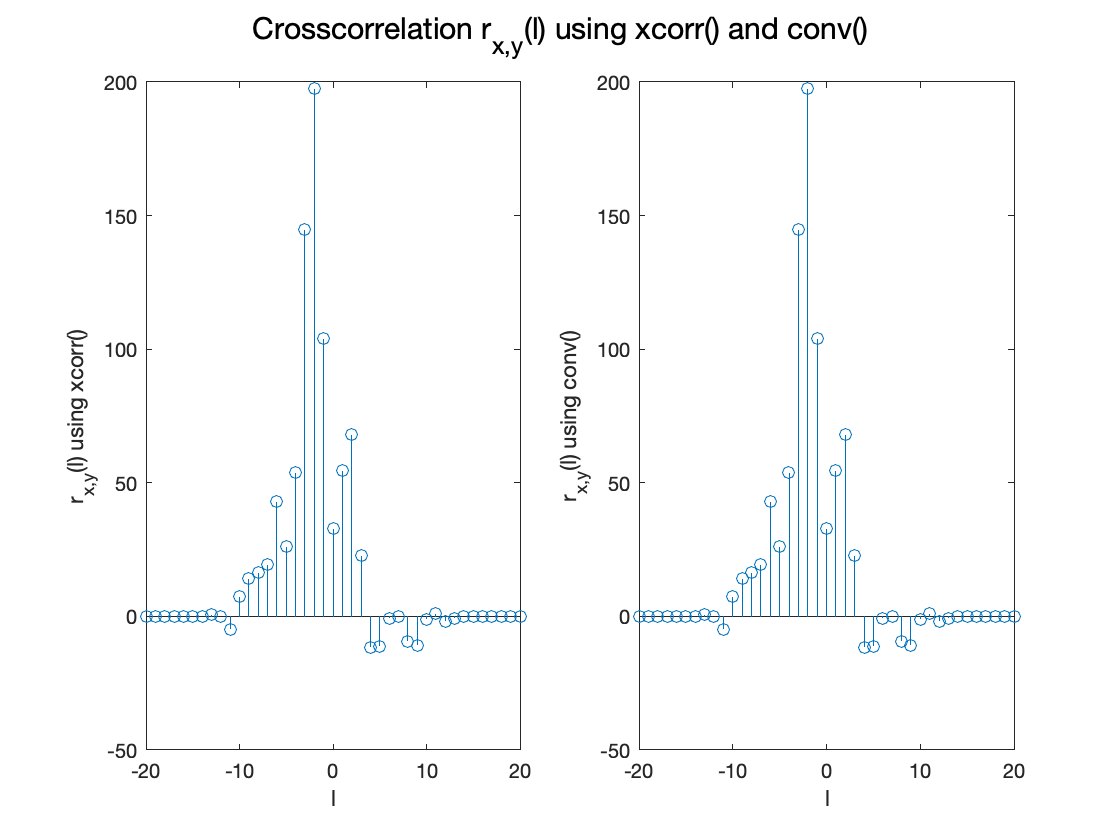

x_values = [3, 11, 7, 0, -1, 4, 2];
% padding x_values with 10 zeroes on either side
x_values = [zeros(1, 10) x_values zeros(1, 10)];

% Mapping the non-zero values in x_values, onto the range (-3 <= n <= 3)
% valid inputs: -13 <= n <= 13
x = @(n) x_values(n + 14);

% noise corrupted and shifted version of x
% valid inputs: -11 <= n <= 15
y = @(n) x(n-2) + w(n);

% Defining the input range
n = -10:10; 

xn = x(n);
yn = y(n);

% correlation using xcorr()
[r_xy_1, lags_xy] = xcorr(xn, yn);
[r_xx_1, lags_xx] = xcorr(xn, xn);

% correlation using conv()
r_xy_2 = conv(xn, flip(yn));
r_xx_2 = conv(xn, flip(xn));

figure;
subplot(1, 2, 1);
stem(lags_xy, r_xy_1);
xlabel("l"); ylabel("r_{x,y}(l) using xcorr()");
subplot(1, 2, 2);
stem(lags_xy, r_xy_2);
xlabel("l"); ylabel("r_{x,y}(l) using conv()");
sgtitle("Crosscorrelation r_{x,y}(l) using xcorr() and conv()");

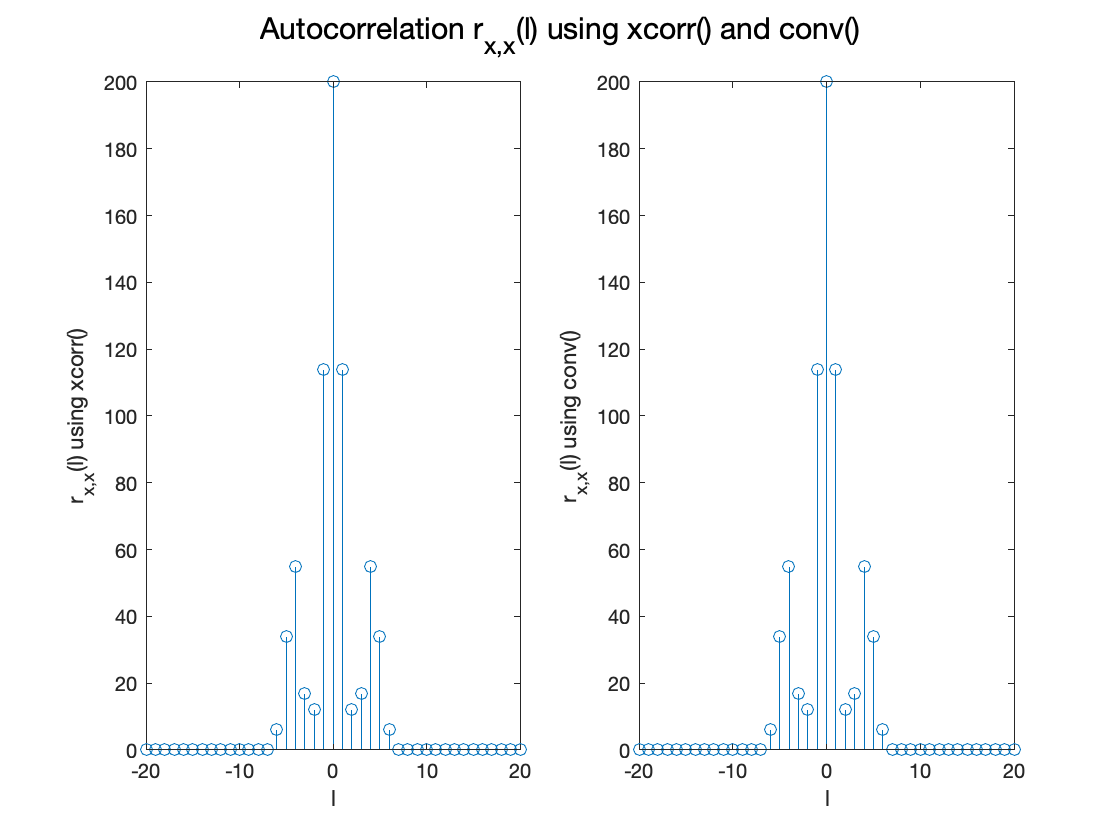

figure;
subplot(1, 2, 1);
stem(lags_xx, r_xx_1);
xlabel("l"); ylabel("r_{x,x}(l) using xcorr()"); axis([-20, 20, 0 , 200]);
subplot(1, 2, 2);
stem(lags_xx, r_xx_2);
xlabel("l"); ylabel("r_{x,x}(l) using conv()"); axis([-20,20, 0 , 200]);
sgtitle("Autocorrelation r_{x,x}(l) using xcorr() and conv()");

**Q4:**

(a) Since $y(n)$ is a sum of $x(n)$ and the delayed, scaled component $\alpha x(n-k)$, the cross correlation of $x(n)$and $y(n)$will be a sum of the autocorrelation $r_{x,x}(l)$with a scaled and equally time shifted (in the opposite direction) version of the autocorrelation, $\alpha r_{x,x}(l + k)$. This can be proven mathematically:


$$r_{x,y}(l) = x(n) \star y(n)$$


          
$$= x(n) \star [x(n) + \alpha x(n-k)]$$


          
$$= [x(n) \star x(n)] + [x(n) \star \alpha x(n-k)]$$


          
$$= r_{x,x}(l) + \alpha \displaystyle\sum_{l = -\infty}^{+\infty}{x(n) \cdot x(n-k-l)}$$


          
$$= r_{x,x}(l) + \alpha \displaystyle\sum_{l+k=-\infty}^{+\infty}{x(n) \cdot x(n - (l+k))}$$



$$r_{x,y}(l) = r_{x,x}(l) + \alpha r_{x,x}(l+k)$$


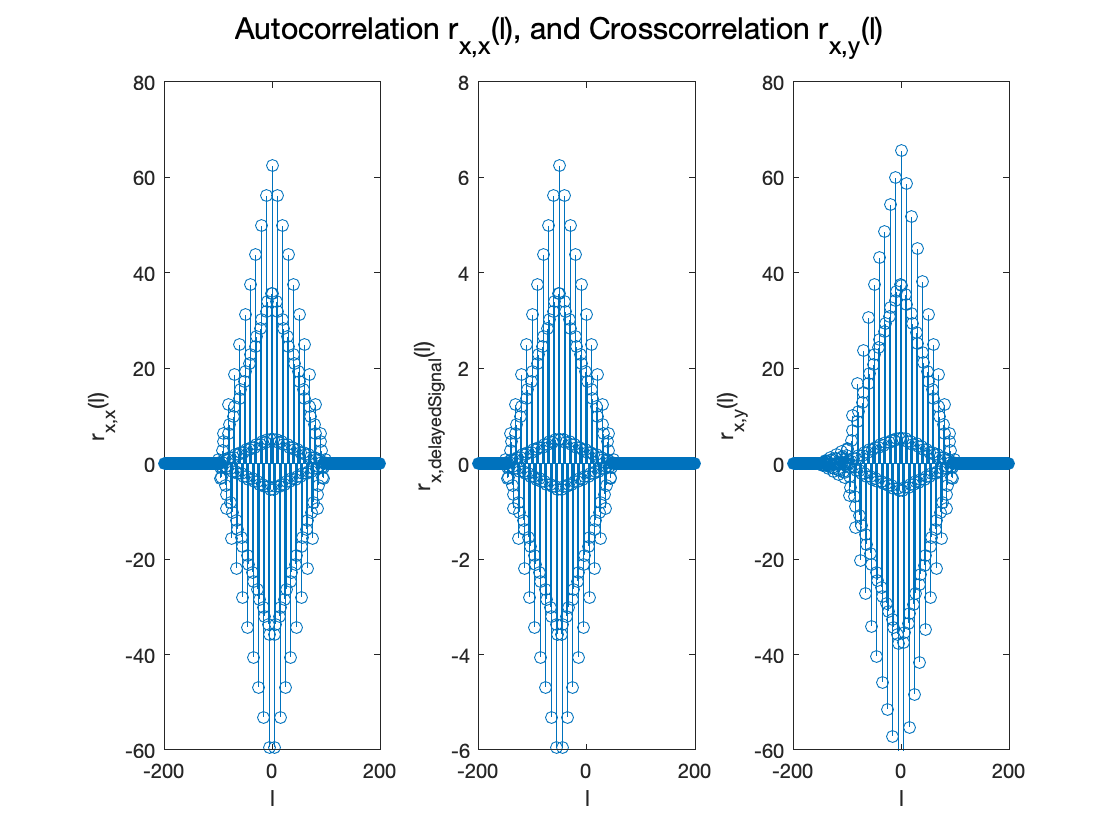

% (b)
alpha = 0.1;
k = 50;

x = @(n) cos(0.2 * pi * n) + (0.5 * cos(0.6 * pi * n));

% Assuming x(n) has 100 data points and is surrounded by zeros on either side
n = 1:100;
xn = [zeros(1, k) x(n) zeros(1, k)];

% constructing the signal delayed by k
delayedSignal = [zeros(1, k) xn(1:end - k)];

% constructing the series y(n)
yn = xn + (alpha * delayedSignal);

[r_xy, lags_xy] = xcorr(xn, yn);
[r_xx, lags_xx] = xcorr(xn, xn);
r_x_delayedSignal = r_xy - r_xx;

figure;
subplot(1, 3, 1);
stem(lags_xx, r_xx);
xlabel("l"); ylabel("r_{x,x}(l)");

subplot(1, 3, 2);
stem(lags_xx, r_x_delayedSignal);
xlabel("l"); ylabel("r_{x,delayedSignal}(l)");

subplot(1, 3, 3);
stem(lags_xy, r_xy);
xlabel("l"); ylabel("r_{x,y}(l)"); axis([-200, 200, -60, 80]);
sgtitle("Autocorrelation r_{x,x}(l), and Crosscorrelation r_{x,y}(l)");

From the analysis done in part (a), we know that second component of the crosscorrelation of $x(n)$ and $y(n)$ holds the information about $k$ and $\alpha$. This component is the crosscorrelation of $x(n)$ and the delayed signal, and has been computed by subtracting the autocorrelation of $x(n)$ from the crosscorrelation $r_{x,y}(l)$.

Since the crosscorrelation series achieves a maxima for those values of lag ($l$) where the two waveforms are the most similar, the index at which the crosscorrelation series achieves a maxima can be used to determine the lag/delay.

Moreover, the effect of the scaling constant is to simply scale the crosscorrelation output by the value of the constant. Hence, the scaling constant can be found by dividing the maximum value of the crosscorrelation series by the maximum value of the autocorrelation series.

% Obtaining the value of k from crosscorrelation of x(n) and delayedSignal
[maxval, argmax] = max(r_x_delayedSignal);
delay = lags_xy(argmax);

% Obtaining the value of alpha
scalingFactor = max(r_x_delayedSignal) / max(r_xx);

display(delay);

delay = -50

display(scalingFactor);

scalingFactor = 0.1000

Thus, we have successfully extracted the values of $k$ and $\alpha$.